# Define distributions

mean = 50

mean = 50

uniform = randi([0 100],100000, 1);
gaussian = normrnd(mean,5,[100000 1]); 

## Rayleigh distribution:

alpha = mean/sqrt(pi/2)

alpha = 39.8942

vari = (2-pi/2)*alpha^2

vari = 683.0989

rayleigh = normrnd(mean, sqrt(vari), [100000 1]);

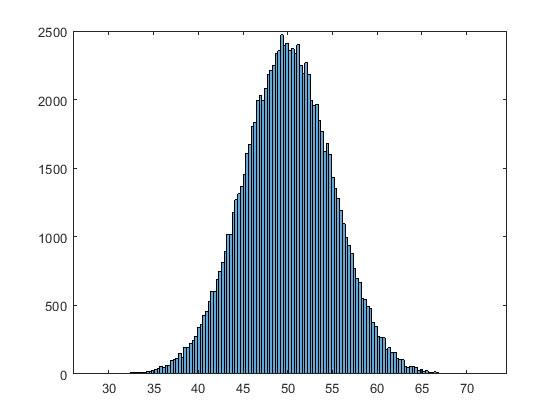

histogram(gaussian)

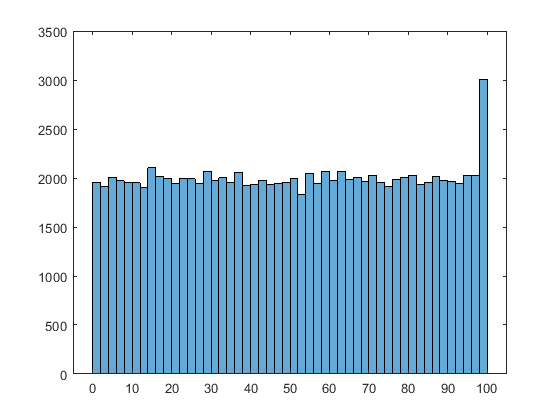

histogram(uniform)

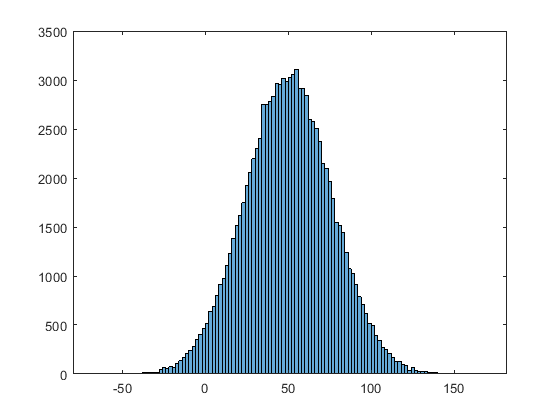

histogram(rayleigh)

## Ideal Estimator Given no observation

x_prediction = mean % always predict mean a/c to l.m.s criterion

x_prediction =     50


% calculate error with all distribution: 
uniform_error = uniform - x_prediction;
gaussian_error = gaussian - x_prediction; 
rayleigh_error = rayleigh - x_prediction; 
c1_base = sum(uniform_error.^2)

c1_base =     85014905


c2_base = sum(gaussian_error.^2)

c2_base =    2.5003e+06


c3_base = sum(rayleigh_error.^2)

c3_base =    6.8434e+07


## Change estimator to a random value and check if error decreases

x_prediction = randi([0, 100])

x_prediction =     99


% calculate error with all distribution: 
uniform_error = uniform - x_prediction;
gaussian_error = gaussian - x_prediction; 
rayleigh_error = rayleigh - x_prediction; 
c1 = sum(uniform_error.^2)

c1 =    324359227


c2 = sum(gaussian_error.^2)

c2 =    2.4257e+08


c3 = sum(rayleigh_error.^2)

c3 =     3.078e+08



e_coefficient = [c1/c1_base c2/c2_base c3/c3_base].*100; 
e_coefficient+" % of c_1"

ans = 1×3 string array
    "381.53219 % of c_1"    "9701.7174 % of c_1"    "449.78495 % of c_1"


% since e_coefficient contains all percentages greater than 100, the l.m.s
% criterion provides a good estimator given no information about the
% distribution, with only mean and variance of the distribution known. 